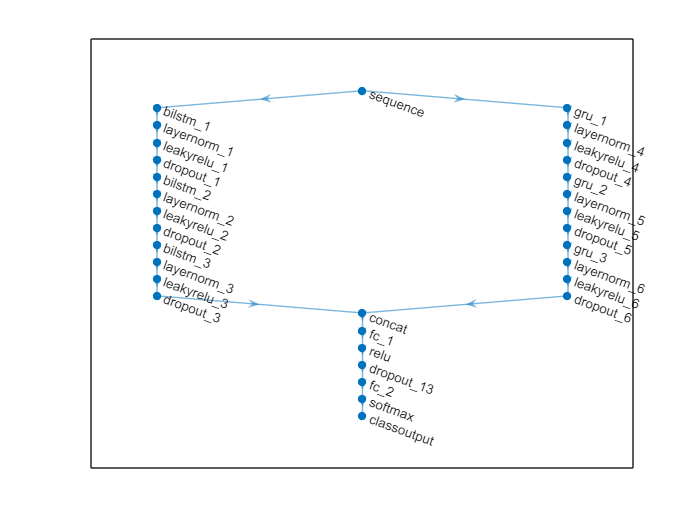

trainingData = abs(fft(filterhaar3TEtrain));
testingData = abs(fft(filterhaar3TEtest));

% trainingData = filter1_TEtrain;
% testingData = filter1_TEtest;

trainnumsamples = 480; 
testnumsamples = 800;


C21train={categorical([...
    ones(1,trainnumsamples),...
    ones(1,trainnumsamples)*2, ...
    ones(1,trainnumsamples)*3, ...
    ones(1,trainnumsamples)*4, ...
    ones(1,trainnumsamples)*5, ...
    ones(1,trainnumsamples)*6, ...
    ones(1,trainnumsamples)*7, ...
    ones(1,trainnumsamples)*8, ...
    ones(1,trainnumsamples)*9, ...
    ones(1,trainnumsamples)*10, ...
    ones(1,trainnumsamples)*11, ...
    ones(1,trainnumsamples)*12, ...
    ones(1,trainnumsamples)*13, ...
    ones(1,trainnumsamples)*14, ...
    ones(1,trainnumsamples)*15, ...
    ones(1,trainnumsamples)*16, ...
    ones(1,trainnumsamples)*17, ...
    ones(1,trainnumsamples)*18, ...
    ones(1,trainnumsamples)*19, ...
    ones(1,trainnumsamples)*20, ...
    ones(1,trainnumsamples)*21])};
C21test={categorical([...
    ones(1,testnumsamples),...
    ones(1,testnumsamples)*2, ...
    ones(1,testnumsamples)*3, ...
    ones(1,testnumsamples)*4, ...
    ones(1,testnumsamples)*5, ...
    ones(1,testnumsamples)*6, ...
    ones(1,testnumsamples)*7, ...
    ones(1,testnumsamples)*8, ...
    ones(1,testnumsamples)*9, ...
    ones(1,testnumsamples)*10, ...
    ones(1,testnumsamples)*11, ...
    ones(1,testnumsamples)*12, ...
    ones(1,testnumsamples)*13, ...
    ones(1,testnumsamples)*14, ...
    ones(1,testnumsamples)*15, ...
    ones(1,testnumsamples)*16, ...
    ones(1,testnumsamples)*17, ...
    ones(1,testnumsamples)*18, ...
    ones(1,testnumsamples)*19, ...
    ones(1,testnumsamples)*20, ...
    ones(1,testnumsamples)*21])};


XTrain = helperPreprocess(trainingData,10080);
YTrain = C21train;

XTest = helperPreprocess(testingData,16800); 
YTest = C21test;


trainMean = mean(trainingData(:,:))';
trainSigma = std(trainingData(:,:))';

testMean = mean(testingData(:,:))';
testSigma = std(testingData(:,:))';

XTrain = helperNormalize(XTrain, trainMean, trainSigma);
XTest = helperNormalize(XTest, testMean, testSigma);


lgraph = layerGraph();


tempLayers = sequenceInputLayer(52,"Name","sequence");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    bilstmLayer(64,"Name","bilstm_1")
    layerNormalizationLayer("Name","layernorm_1")
    leakyReluLayer(0.1,"Name","leakyrelu_1")
    dropoutLayer(0.2,"Name","dropout_1")
    bilstmLayer(64,"Name","bilstm_2")
    layerNormalizationLayer("Name","layernorm_2")
    leakyReluLayer(0.1,"Name","leakyrelu_2")
    dropoutLayer(0.2,"Name","dropout_2")
    bilstmLayer(64,"Name","bilstm_3")  
    layerNormalizationLayer("Name","layernorm_3")
    leakyReluLayer(0.1,"Name","leakyrelu_3")
    dropoutLayer(0.2,"Name","dropout_3")
    ];  
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    gruLayer(128,"Name","gru_1")
    layerNormalizationLayer("Name","layernorm_4")
    leakyReluLayer(0.1,"Name","leakyrelu_4")
    dropoutLayer(0.2,"Name","dropout_4")
    gruLayer(128,"Name","gru_2")
    layerNormalizationLayer("Name","layernorm_5")
    leakyReluLayer(0.1,"Name","leakyrelu_5")
    dropoutLayer(0.2,"Name","dropout_5")
    gruLayer(128,"Name","gru_3")
    layerNormalizationLayer("Name","layernorm_6")
    leakyReluLayer(0.1,"Name","leakyrelu_6")
    dropoutLayer(0.2,"Name","dropout_6")
    ];
lgraph = addLayers(lgraph,tempLayers);


tempLayers = [
    concatenationLayer(1,2,"Name","concat")
    fullyConnectedLayer(64,"Name","fc_1")
    reluLayer("Name","relu")
    dropoutLayer(0.4,"Name","dropout_13")
    fullyConnectedLayer(21,"Name","fc_2")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];
lgraph = addLayers(lgraph,tempLayers);

% 清理辅助变量
clear tempLayers;


lgraph = connectLayers(lgraph,"sequence","bilstm_1");
lgraph = connectLayers(lgraph,"sequence","gru_1");
% lgraph = connectLayers(lgraph,"sequence","conv1d_1");
lgraph = connectLayers(lgraph,"dropout_3","concat/in1");
lgraph = connectLayers(lgraph,"dropout_6","concat/in2");
% lgraph = connectLayers(lgraph,"dropout_4","fc_1");


plot(lgraph);




options = trainingOptions('adam', ...
    'MaxEpochs',400, ...
    'MiniBatchSize',1, ...
    'ValidationData',{XTest,YTest}, ...
    'ValidationFrequency',25, ...
    'Plots','training-progress', ...
    'OutputFcn',@(info)stopIfAccuracyNotImproving(info,20));

在单 GPU 上训练。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量准确度　　｜　　验证准确度　　｜　　小批量损失　　｜　　验证损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：０８　｜　　　　５．８６％　｜　　１５．４５％　｜　　３．５５３２　｜　２．８４０１　｜　　０．００１０　｜
｜　　２５　｜　　　２５　｜　　　　　００：０１：２９　｜　　　３７．７１％　｜　　４３．０５％　｜　　１．７０１４　｜　１．３９８２　｜　　０．００１０　｜
｜　　５０　｜　　　５０　｜　　　　　００：０２：５３　｜　　　５７．４８％　｜　　６０．０６％　｜　　０．９５５９　｜　０．８７６７　｜　　０．００１０　｜
｜　　７５　｜　　　７５　｜　　　　　００：０４：１６　｜　　　７６．７９％　｜　　７１．９６％　｜　　０．５７６１　｜　０．８０４７　｜　　０．００１０　｜
｜　１００　｜　　１００　｜　　　　　００：０５：３８　｜　　　９４．１６％　｜　　８８．７１％　｜　　０．２１０９　｜　０．４００８　｜　　０．００１０　｜
｜　１２５　｜　　１２５　｜　　　　　００：０７：０１　｜　　　９３．７９％　｜　　９１．８２％　｜　　０．２３６９　｜　０．２８３３　｜　　０．００１０　｜
｜　１５０　｜　　１５０　｜　　　　　００：０８：２３　｜　　　９８．５３％　｜　　９３．８０％　｜　　０．０６２１　｜　０．２１７１　｜　　０．００１０　｜
｜　１７５　｜　　１７５　｜　　　　　００：０９：４６　｜　　　９９．０７％　｜　　９６．０４％　｜　　０．０３８６　｜　０．１９５０　｜　　０．００１０　｜
｜　２００　｜　　２００　｜　　　　　００：１１：０８　

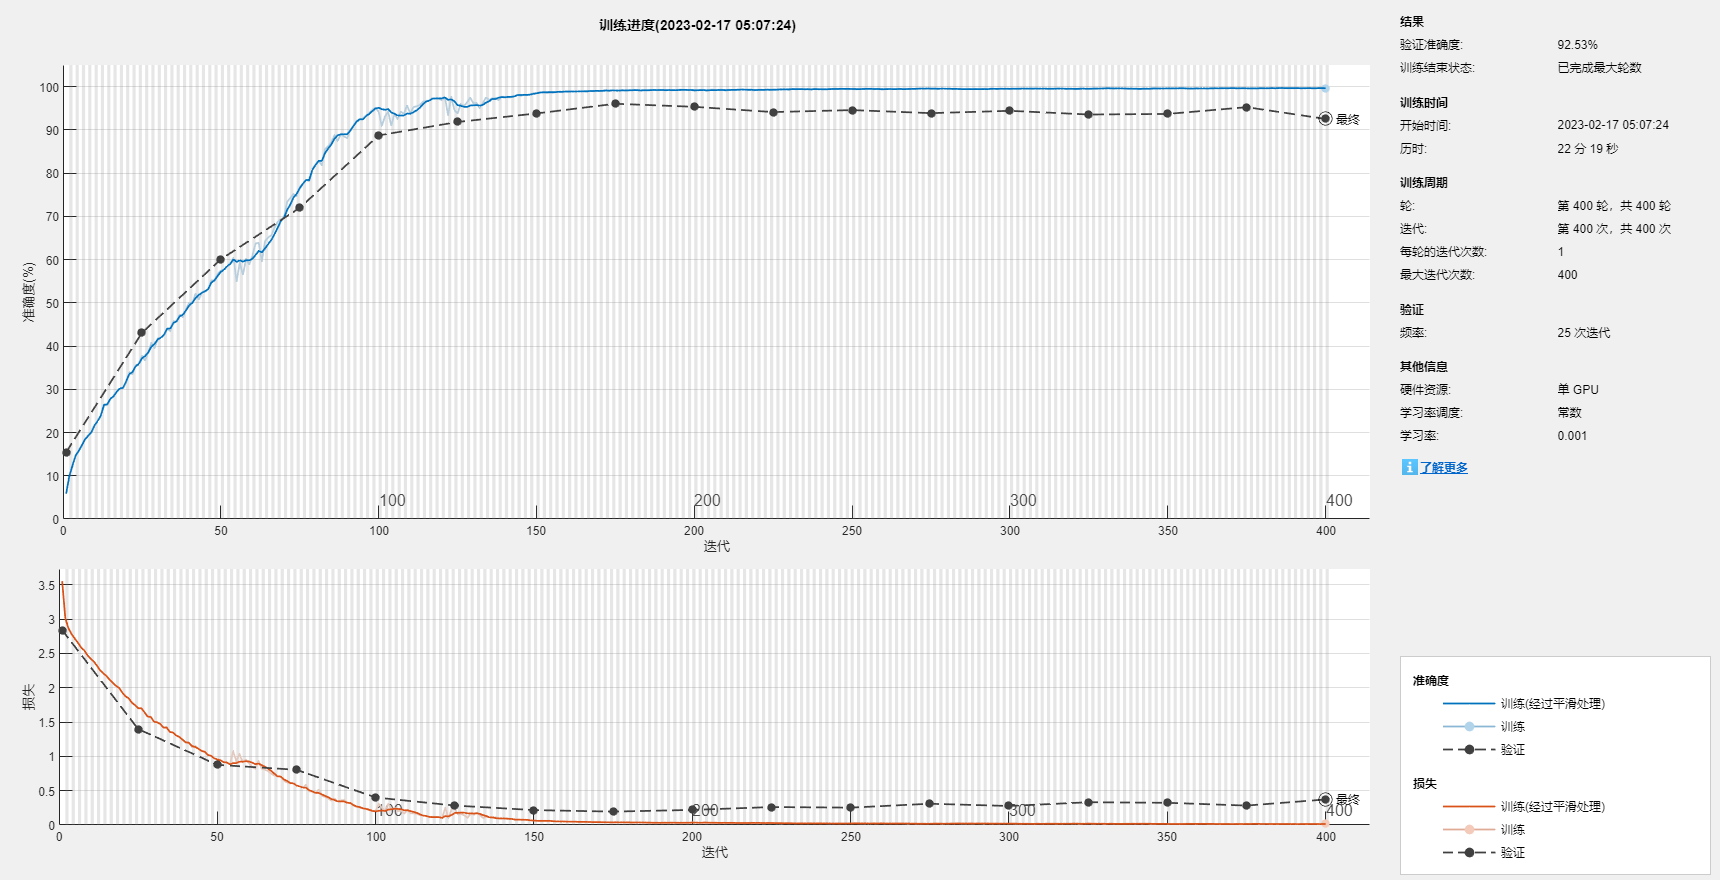

[net,info] = trainNetwork(XTrain,YTrain,lgraph,options);


YPred = classify(net,XTest);

accuracy = mean(YPred{1} == YTest{1})

accuracy = 0.9253

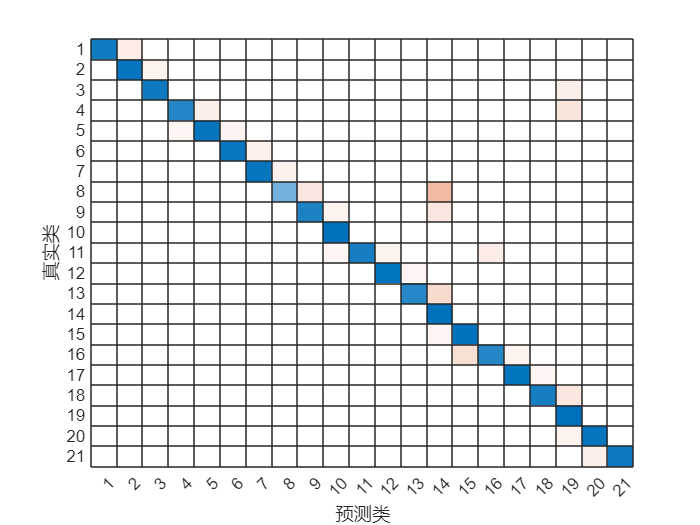


confusionchart(YTest{1},YPred{1})



YPred = double(YPred{1});
YTest = double(YTest{1});

accuracy01 = mean(YPred(1:800) == YTest(1:800));
accuracy02 = mean(YPred(801:1600) == YTest(801:1600));
accuracy03 = mean(YPred(1601:2400) == YTest(1601:2400));
accuracy04 = mean(YPred(2401:3200) == YTest(2401:3200));
accuracy05 = mean(YPred(3201:4000) == YTest(3201:4000));
accuracy06 = mean(YPred(4001:4800) == YTest(4001:4800));
accuracy07 = mean(YPred(4801:5600) == YTest(4801:5600));
accuracy08 = mean(YPred(5601:6400) == YTest(5601:6400));
accuracy09 = mean(YPred(6401:7200) == YTest(6401:7200));
accuracy10 = mean(YPred(7201:8000) == YTest(7201:8000));
accuracy11 = mean(YPred(8001:8800) == YTest(8001:8800));
accuracy12 = mean(YPred(8801:9600) == YTest(8801:9600));
accuracy13 = mean(YPred(9601:10400) == YTest(9601:10400));
accuracy14 = mean(YPred(10401:11200) == YTest(10401:11200));
accuracy15 = mean(YPred(11201:12000) == YTest(11201:12000));
accuracy16 = mean(YPred(12001:12800) == YTest(12001:12800));
accuracy17 = mean(YPred(12801:13600) == YTest(12801:13600));
accuracy18 = mean(YPred(13601:14400) == YTest(13601:14400));
accuracy19 = mean(YPred(14401:15200) == YTest(14401:15200));
accuracy20 = mean(YPred(15201:16000) == YTest(15201:16000));
accuracy21 = mean(YPred(16001:16800) == YTest(16001:16800));



function processed = helperPreprocess(mydata,limit)
    H = size(mydata);
    processed = {};
    for ind = 1:limit:H
        x = mydata(ind:(ind+(limit-1)),:);
        processed = [processed; x'];
    end

end

function data = helperNormalize(data,m,s)
    for ind = 1:size(data)
        data{ind} = (data{ind} - m)./s;
    end
end

function stop = stopIfAccuracyNotImproving(info,N)
    stop = false;                         
    % 跟踪最佳验证准确度和准确度未提高的验证次数。
    persistent bestValAccuracy
    persistent valLag                     
    % 训练开始时清除变量。
    if info.State == "start"
        bestValAccuracy = 0;
        valLag = 0;
    elseif ~isempty(info.ValidationLoss)  
            % 将当前验证准确度与迄今为止的最佳准确度进行比较，或者将最佳准确度设置为当前准确度，或者增加没有改进的验证次数。
            if info.ValidationAccuracy > bestValAccuracy    
                valLag = 0;   
                bestValAccuracy = info.ValidationAccuracy;    
            else    
                valLag = valLag + 1;    
            end    
        % 如果验证滞后至少为 N，即至少 N 次验证的验证准确度没有提高，则返回 true 并停止训练。
        if valLag >= N    
            stop = true;    
        end   
    end
end